close all
clear all
clc

% % Train patch images
% imds = imageDatastore(fullfile('S3Dataset'), ...
%     'IncludeSubfolders',true,'LabelSource','foldernames');
%Current folder I:\학회논문\2020_RS_2\S3
cd ('H:\2022 대학원\reagain\complete\processing6');
imds = imageDatastore(fullfile('H:\2022 대학원\reagain\과학기지\test2'),...
       'FileExtensions','.mat','ReadFcn',@matReader,"IncludeSubfolders",true,"LabelSource","foldernames");   

%% check the input 
labelCount = countEachLabel(imds)
img = readimage(imds,1);
size(img)

%figure
%numImage = img;
%perm = randperm(numImage,20);
%for i = 1:20
%    subplot(4,5,i);
%    imshow(imds.Files{perm(i)});
%    drawnow;
%end

%% model setting
%numTrainFiles = 1000;
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);

layers = [
    imageInputLayer([128 128 10], 'Name', 'input')
    
    convolution2dLayer(3,8,'Padding','same','Name', 'conv_1')
    batchNormalizationLayer('Name','batchnorm_1')
    reluLayer('Name','relu_1')
    
    %maxPooling2dLayer(2,'Stride',2)
    maxPooling2dLayer(3,'Stride',3, 'Name', 'maxpool_1')
    
    convolution2dLayer(3,16,'Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','batchnorm_2')
    reluLayer('Name','relu_2')
    
    %maxPooling2dLayer(2,'Stride',2)
    maxPooling2dLayer(3,'Stride',3,'Name','maxpool_2')
    
    convolution2dLayer(3,32,'Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','batchnorm_3')
    reluLayer('Name','relu_3')
    
    %fullyConnectedLayer(2)
    fullyConnectedLayer(3,'Name','fc')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];

MaxEpochs = 10;

options = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',MaxEpochs, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment',"auto" ...
    );

net = trainNetwork(imdsTrain,layers,options);

%% save the net file 
outputDir = 'H:\2022 대학원\reagain\과학기지\test2_net';
outputFile = fullfile(outputDir, 'net.mat');
save(outputFile, 'net')

%Test accuracy
YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)
%YVal = cellstr(YValidation);
%YVal = str2double(YVal);
%YPre = cellstr(YPred);
%YPre = str2double(YPre);
%YVal = YVal';
%YPre = YPre';
plotconfusion(YValidation, YPred)  %Show confusion matrix plot

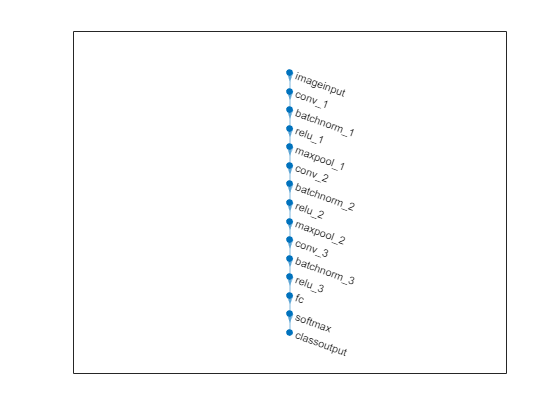

%% calculate precision, recall and f1-score
cm = confusionmat(YValidation, YPred)
cmt = cm'
diagonal = diag(cmt)
sum_of_rows = sum(cmt, 2)


precision = diagonal ./ sum_of_rows 
overall_precision = mean(precision) % 모델이 true라고 예측한 것 중 실제 true의 비율

sum_of_columns = sum(cmt, 1)

recall = diagonal ./ sum_of_columns'
overall_recall = mean(recall) % 실제 true 값 중에서 모델이 true라고 예측한 것의 비율

f1_score = 2*((overall_precision*overall_recall)/(overall_precision+overall_recall)) % precision과 recall의 조화평균

lgraph = layerGraph(layers);
lgraph = layerGraph(net);
figure
plot(lgraph)